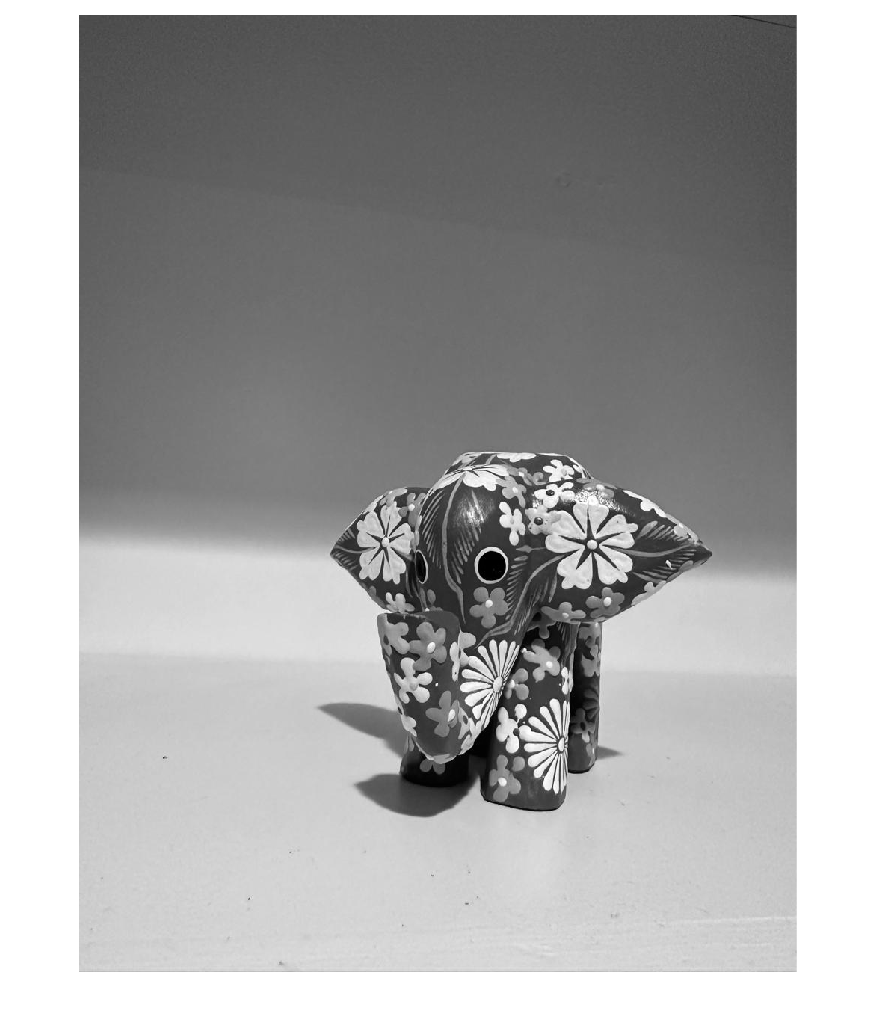

boxImage = imread('/Users/Harsh/Documents/GSU_Spring/ComputerVision/Harsh_Assignment_3/elephant.jpeg');
boxImage = im2gray(boxImage);
figure;
imshow(boxImage);

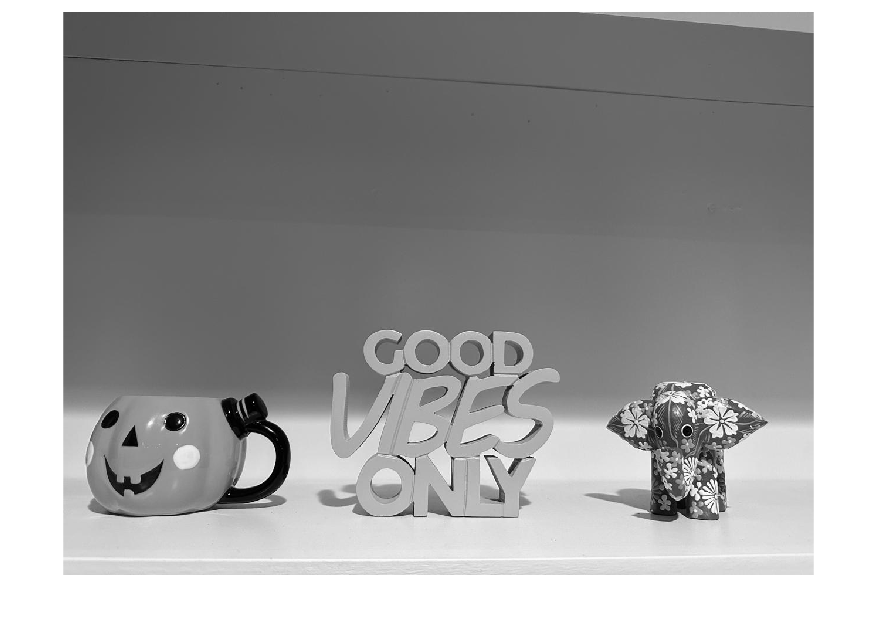



sceneImage = imread('/Users/Harsh/Documents/GSU_Spring/ComputerVision/Harsh_Assignment_3/clutter.jpeg');
sceneImage = im2gray(sceneImage);
figure;
imshow(sceneImage);

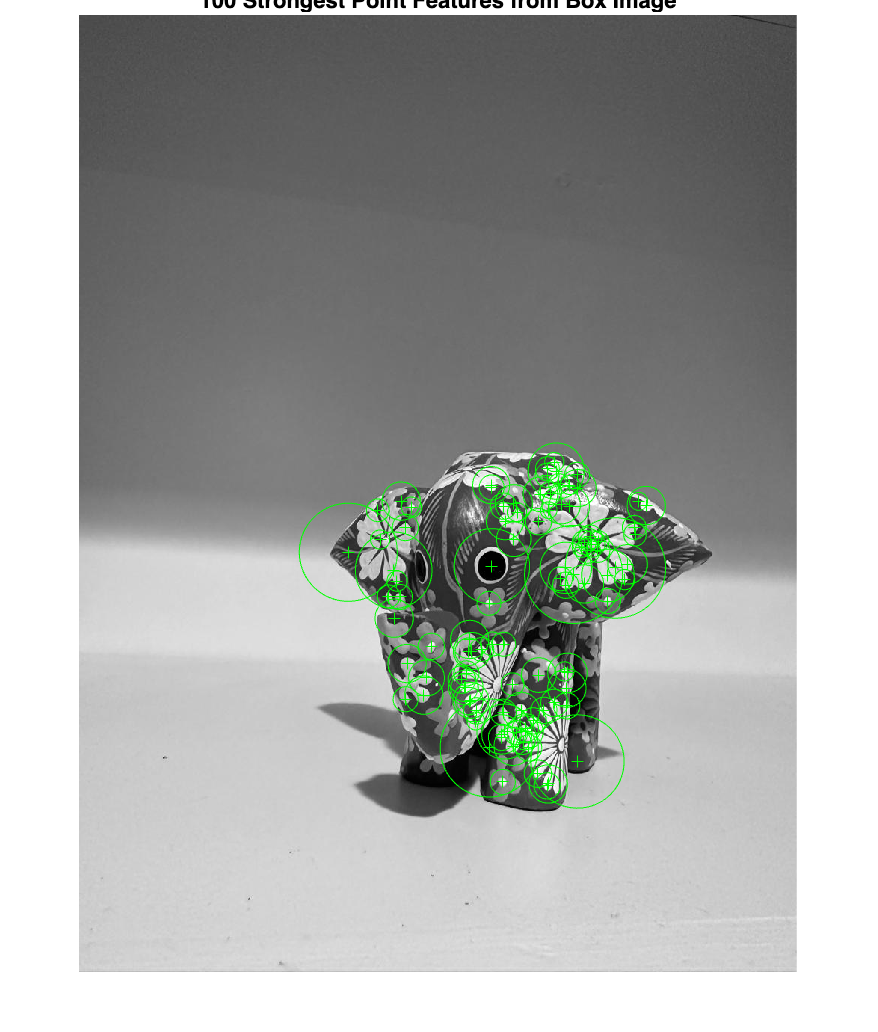


boxPoints = detectSURFFeatures(boxImage);

figure;
imshow(boxImage);
title('100 Strongest Point Features from Box Image');
hold on;
plot(selectStrongest(boxPoints, 100));

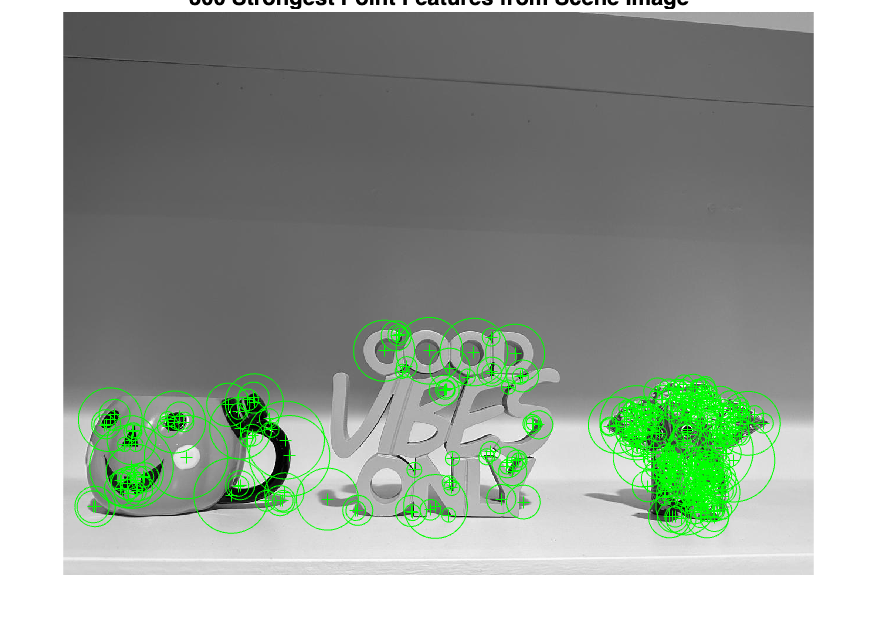


scenePoints = detectSURFFeatures(sceneImage);

figure;
imshow(sceneImage);
title('300 Strongest Point Features from Scene Image');
hold on;
plot(selectStrongest(scenePoints, 300));

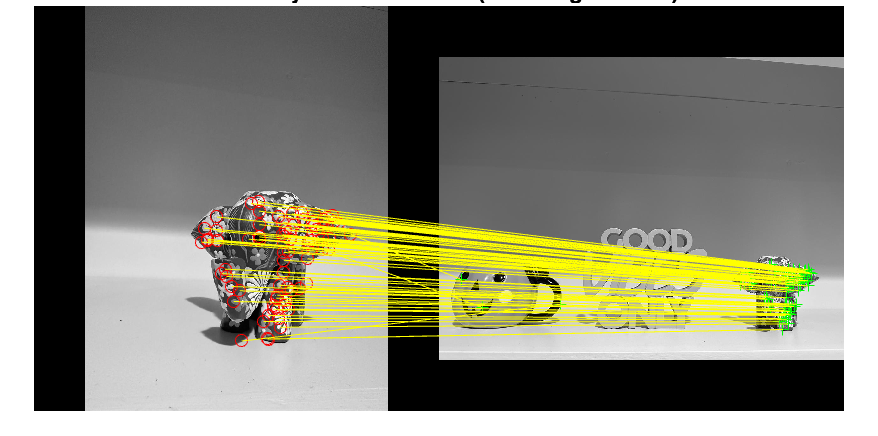


 
[boxFeatures, boxPoints] = extractFeatures(boxImage, boxPoints);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

boxPairs = matchFeatures(boxFeatures, sceneFeatures);

matchedBoxPoints = boxPoints(boxPairs(:, 1), :);
matchedScenePoints = scenePoints(boxPairs(:, 2), :);
figure;
showMatchedFeatures(boxImage, sceneImage, matchedBoxPoints, ...
matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

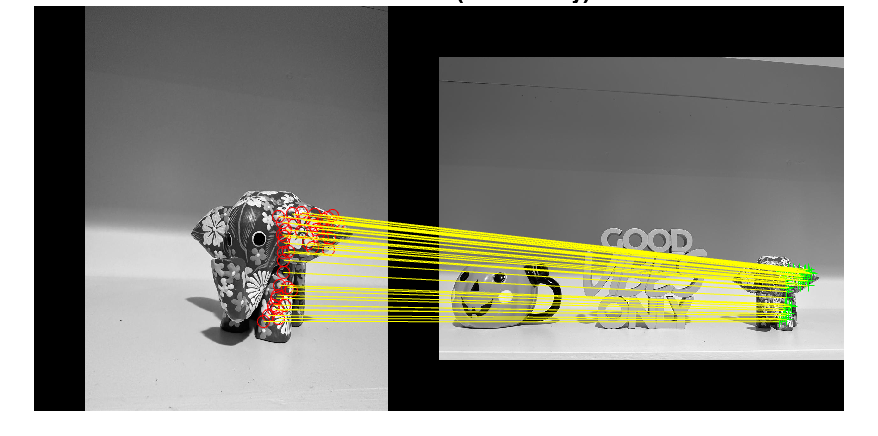



% % [tform, inlierIdx] = estgeotform2d(matchedBoxPoints, matchedScenePoints, 'affine');
[tform, inlierIdx] = estimateGeometricTransform2D(matchedBoxPoints, matchedScenePoints, 'affine');
inlierBoxPoints   = matchedBoxPoints(inlierIdx, :);
inlierScenePoints = matchedScenePoints(inlierIdx, :);

figure;
showMatchedFeatures(boxImage, sceneImage, inlierBoxPoints, ...
    inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

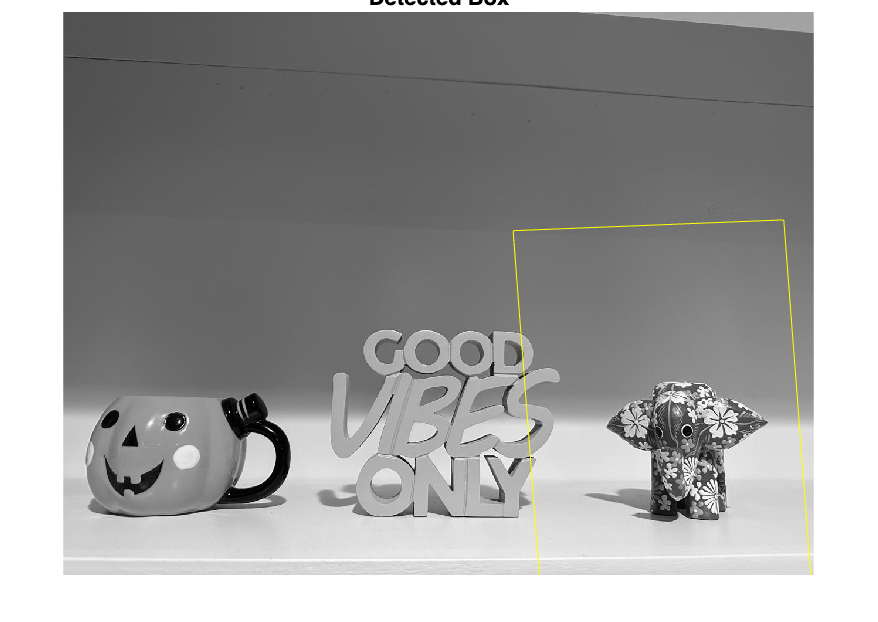



boxPolygon = [1, 1;...                           % top-left
        size(boxImage, 2), 1;...                 % top-right
        size(boxImage, 2), size(boxImage, 1);... % bottom-right
        1, size(boxImage, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon

newBoxPolygon = transformPointsForward(tform, boxPolygon);

figure;
imshow(sceneImage);
hold on;
line(newBoxPolygon(:, 1), newBoxPolygon(:, 2), Color='y');
title('Detected Box');